% Physical Parameters
mb = 300;    % kg
mw = 60;     % kg
bs = 1000;      % N/m/m/s
ks = 16000;     % N/m
kt = 190000;    % N/m

% State Matrices
A = [0 1 0 0;
     -ks/mb -bs/mb ks/mb bs/mb;
     0 0 0 1;
     ks/mw bs/mw (-ks-kt)/mw -bs/mw]

A = 1.0e+03 *

         0    0.0010         0         0
   -0.0533   -0.0033    0.0533    0.0033
         0         0         0    0.0010
    0.2667    0.0167   -3.4333   -0.0167



B = [0 0;
     0 10^3/mb;
     0 0;
     kt/mw -10^3/mw]

B = 1.0e+03 *

         0         0
         0    0.0033
         0         0
    3.1667   -0.0167



C = [1 0 0 0;
     1 0 -1 0;
     A(2, :)]

C =     1.0000         0         0         0
    1.0000         0   -1.0000         0
  -53.3333   -3.3333   53.3333    3.3333



D = [0 0;
     0 0;
     B(2,:)]

D =          0         0
         0         0
         0    3.3333



qcar = ss(A,B,C,D);
qcar.StateName = {'body travel (m)';'body vel (m/s)';...
          'wheel travel (m)';'wheel vel (m/s)'};
qcar.InputName = {'r';'fs'};
qcar.OutputName = {'xb';'sd';'ab'};

Tire hop frequency

tzero(qcar({'xb', 'ab'}, 'fs'))

ans =   -0.0000 +56.2731i
  -0.0000 -56.2731i


zero(qcar('sd', 'fs'))

ans =    0.0000 +22.9734i
   0.0000 -22.9734i


Open Loop gain

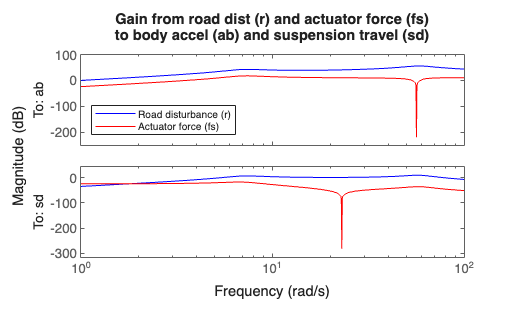

bodemag(qcar({'ab','sd'},'r'),'b',qcar({'ab','sd'},'fs'),'r',{1 100});
legend('Road disturbance (r)','Actuator force (fs)','location','SouthWest')
title(['Gain from road dist (r) and actuator force (fs)' newline ...
    'to body accel (ab) and suspension travel (sd)'])

Uncertain Actuator Model:

Hydraulic actuator connected between mb and mw. Nominal actuator dynamics represented by the first order transfer function 1/(1 + s/60) with a max displacement of 0.05 m.

ActNom = tf(1, [1/60 1])


ActNom =
 
        1
  -------------
  0.01667 s + 1
 
Continuous-time transfer function.
Model Properties


This nominal model only approximates the physical actuator dynamics. We  can use a family of actuator models to account for modeling errors and  variability in the actuator and quarter-car models. This family consists of a nominal model with a frequency-dependent amount of uncertainty. At low frequency, below 3 rad/s, the model can vary up to 40% from its  nominal value. Around 3 rad/s, the percentage variation starts to  increase. The uncertainty crosses 100% at 15 rad/s and reaches 2000% at  approximately 1000 rad/s. The weighting function Wunc is used to modulate the amount of uncertainty with frequency.

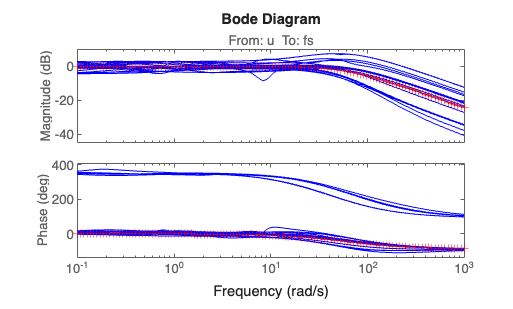

Wunc = makeweight(0.40,15,3);
unc = ultidyn('unc',[1 1],'SampleStateDim',5);
Act = ActNom*(1 + Wunc*unc);
Act.InputName = 'u';
Act.OutputName = 'fs';
rng('default')
bode(Act,'b',Act.NominalValue,'r+',logspace(-1,3,120))

Creating weighting functions

Wroad = ss(0.07);  Wroad.u = 'd1';   Wroad.y = 'r';
Wact = 0.8*tf([1 50],[1 500]);  Wact.u = 'u';  Wact.y = 'e1';
Wd2 = ss(0.01);  Wd2.u = 'd2';   Wd2.y = 'Wd2';
Wd3 = ss(0.5);   Wd3.u = 'd3';   Wd3.y = 'Wd3';

Specify closed-loop targets for the gain from road disturbance to suspension deflection (handling) and body acceleration (comfort). Because of the actuator uncertainty and imaginary-axis zeros, only seek to attenuate disturbances below 10 rad/s.

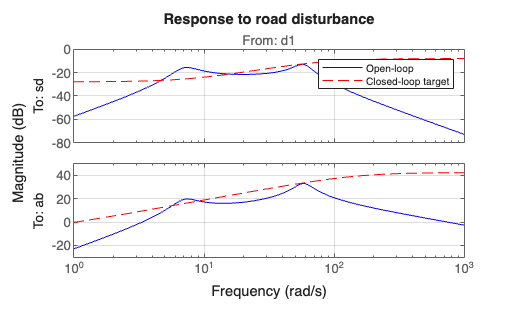

HandlingTarget = 0.04 * tf([1/8 1],[1/80 1]);
ComfortTarget = 0.4 * tf([1/0.45 1],[1/150 1]);

Targets = [HandlingTarget ; ComfortTarget];
bodemag(qcar({'sd','ab'},'r')*Wroad,'b',Targets,'r--',{1,1000}), grid
title('Response to road disturbance')
legend('Open-loop','Closed-loop target')

% Three design points
beta = reshape([0.01 0.5 0.99],[1 1 3]);
Wsd = beta / HandlingTarget;
Wsd.u = 'sd';  Wsd.y = 'e3';
Wab = (1-beta) / ComfortTarget;
Wab.u = 'ab';  Wab.y = 'e2';

sdmeas  = sumblk('y1 = sd+Wd2');
abmeas = sumblk('y2 = ab+Wd3');
ICinputs = {'d1';'d2';'d3';'u'};
ICoutputs = {'e1';'e2';'e3';'y1';'y2'};
qcaric = connect(qcar(2:3,:),Act,Wroad,Wact,Wab,Wsd,Wd2,Wd3,...
                 sdmeas,abmeas,ICinputs,ICoutputs)

3x1 array of uncertain continuous-time state-space models.
Each model has 5 outputs, 4 inputs, 9 states, and the following uncertain blocks:
  unc: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences


**Nominal H-infinity Design**

Use `hinfsyn` to compute an controller for each value of the blending factor 

ncont = 1; % one control signal, u
nmeas = 2; % two measurement signals, sd and ab
K = ss(zeros(ncont,nmeas,3));
gamma = zeros(3,1);
for i=1:3
   [K(:,:,i),~,gamma(i)] = hinfsyn(qcaric(:,:,i),nmeas,ncont);
end

gamma

gamma =     0.9405
    0.6727
    0.8892


The three controllers achieve closed-loop norms of 0.94, 0.67 and 0.89, respectively. Construct the corresponding closed-loop models and compare the gains from road disturbance to for the passive and active suspensions. Observe that all three controllers reduce suspension deflection and body acceleration below the rattlespace frequency (23 rad/s).

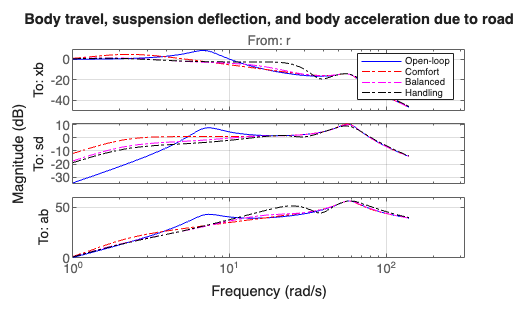

% Closed-loop models
K.u = {'sd','ab'};  K.y = 'u';
CL = connect(qcar,Act.Nominal,K,'r',{'xb';'sd';'ab'});

bodemag(qcar(:,'r'),'b', CL(:,:,1),'r-.', ...
   CL(:,:,2),'m-.', CL(:,:,3),'k-.',{1,140}), grid
legend('Open-loop','Comfort','Balanced','Handling','location','SouthEast')
title('Body travel, suspension deflection, and body acceleration due to road')

**Time-Domain Evaluation**

To further evaluate the three designs, perform time-domain simulations using a road disturbance signal representing a road bump of height 5 cm.

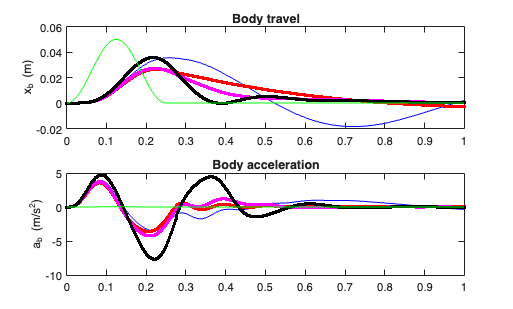

% Road disturbance
t = 0:0.0025:1;
roaddist = zeros(size(t));
roaddist(1:101) = 0.025*(1-cos(8*pi*t(1:101)));

% Closed-loop model
SIMK = connect(qcar,Act.Nominal,K,'r',{'xb';'sd';'ab';'fs'});

% Simulate
p1 = lsim(qcar(:,1),roaddist,t);
y1 = lsim(SIMK(1:4,1,1),roaddist,t);
y2 = lsim(SIMK(1:4,1,2),roaddist,t);
y3 = lsim(SIMK(1:4,1,3),roaddist,t);

% Plot results
subplot(211)
plot(t,p1(:,1),'b',t,y1(:,1),'r.',t,y2(:,1),'m.',t,y3(:,1),'k.',t,roaddist,'g')
title('Body travel'), ylabel('x_b (m)')
subplot(212)
plot(t,p1(:,3),'b',t,y1(:,3),'r.',t,y2(:,3),'m.',t,y3(:,3),'k.',t,roaddist,'g')
title('Body acceleration'), ylabel('a_b (m/s^2)')